# Lab 3 - Problem 4 (PESQ version for local pesq.m)

1) Add white noise to mhint_01_01.wav at SNR = -5, -3, -1, 1, 3, 5 dB. 2) Equalize noisy speech energy to clean speech. 3) Run PESQ and plot PESQ value vs SNR.

This script is written for pesq.m API: scores = pesq(ref_wav, deg_wav) where inputs must be wav filenames (char).

clear; clc; close all;
rng(20260314, 'twister');

knownLab3Dir = '/Users/hwy/Desktop/个人/26春/语音信号处理/lab3';
baseDir = resolveBaseDir(knownLab3Dir);

pesqFile = locateSingleFile('pesq.m', baseDir, knownLab3Dir);
addpath(fileparts(pesqFile), '-begin');

fprintf('Using PESQ function: %s\n', which('pesq'));

Using PESQ function: /Users/hwy/Desktop/个人/26春/语音信号处理/lab3/pesq.m



outDir = fullfile(baseDir, 'lab3_outputs', 'problem4');
if ~exist(outDir, 'dir')
    mkdir(outDir);
end

mhintWav = locateSingleFile('mhint_01_01.wav', baseDir, knownLab3Dir);
[clean, fs] = audioread(mhintWav);
clean = toMonoColumn(clean);
clean = clean - mean(clean);

if ~(fs == 8000 || fs == 16000)
    error('PESQ supports only 8k or 16k sampling rate. Current fs = %d Hz', fs);
end

fprintf('Clean speech: %s\n', mhintWav);

Clean speech: /Users/hwy/Desktop/个人/26春/语音信号处理/lab1/Lab1_12313505_胡伟毅/mhint_01_01.wav


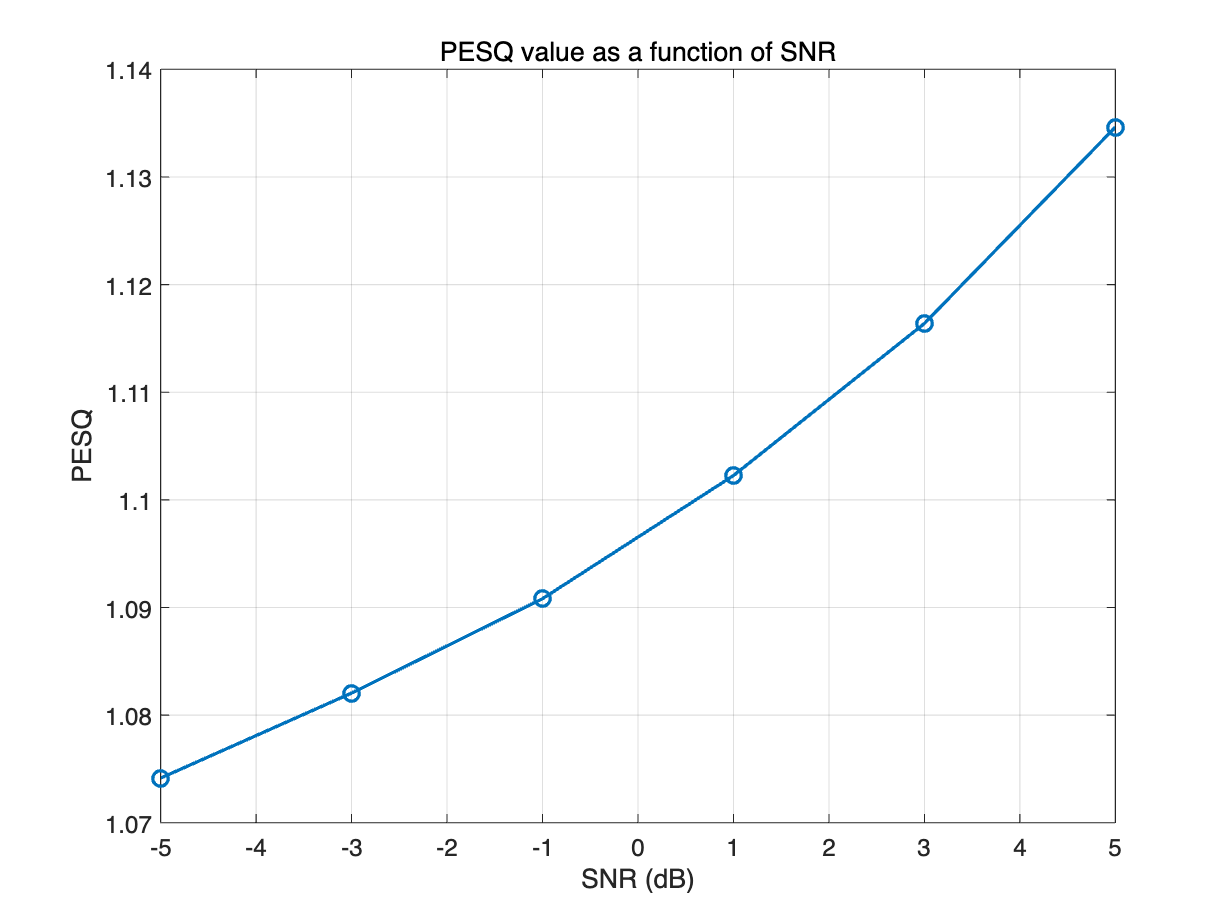


% Reference wav used by PESQ.
refWav = fullfile(outDir, 'P4_ref_clean.wav');
audiowrite(refWav, clean, fs);

snrList = [-5, -3, -1, 1, 3, 5];
snrMeasured = nan(size(snrList));
pesqVal = nan(size(snrList));      % Use MOS-LQO value.

for i = 1:numel(snrList)
    snrTarget = snrList(i);

    [yNoisy, snrActual] = addWhiteNoiseAtSNR(clean, snrTarget);
    yEq = equalizeEnergy(yNoisy, clean);
    snrMeasured(i) = snrActual;

    degWav = fullfile(outDir, sprintf('P4_deg_eq_%+ddB.wav', snrTarget));
    audiowrite(degWav, yEq, fs);

    % pesq.m requires char filenames (not string type).
    scores = pesq(char(refWav), char(degWav));
    scores = double(scores(:).');

    if isempty(scores)
        warning('Empty PESQ output at SNR %d dB.', snrTarget);
        continue;
    end

    % WB: one value (MOS-LQO); NB: two values [raw, MOS-LQO].
    % Keep only final PESQ/MOS-LQO value for report.
    pesqVal(i) = scores(end);
end

T = table(snrList(:), snrMeasured(:), pesqVal(:), ...
    'VariableNames', {'SNR_Target_dB', 'SNR_Actual_dB', 'PESQ'});
writetable(T, fullfile(outDir, 'P4_pesq_vs_snr.csv'));

fig = figure('Name', 'Problem4-PESQ-vs-SNR', 'Color', 'w');
plot(snrList, pesqVal, '-o', 'LineWidth', 1.5, 'MarkerSize', 7);
grid on;
xlabel('SNR (dB)');
ylabel('PESQ');
title('PESQ value as a function of SNR');
saveas(fig, fullfile(outDir, 'P4_pesq_vs_snr.png'));


disp(T);

    SNR_Target_dB    SNR_Actual_dB     PESQ 
    _____________    _____________    ______
         -5               -5          1.0741
         -3               -3          1.0821
         -1               -1          1.0908
          1                1          1.1023
          3                3          1.1164
          5                5          1.1346


fprintf('Problem 4 done.\nOutputs saved in: %s\n', outDir);

Problem 4 done.
Outputs saved in: /Users/hwy/Desktop/个人/26春/语音信号处理/lab3/lab3_outputs/problem4


## Local functions

function baseDir = resolveBaseDir(knownLab3Dir)
    cands = {};

    % Prefer current working folder when running from Live Editor.
    cands{end+1} = pwd; %#ok<AGROW>

    % Try script location if available and not a temporary editor cache path.
    mf = mfilename('fullpath');
    if ~isempty(mf)
        d = fileparts(mf);
        if isempty(strfind(d, [filesep 'Editor_'])) %#ok<STREMP>
            cands{end+1} = d; %#ok<AGROW>
        end
    end

    cands{end+1} = knownLab3Dir; %#ok<AGROW>

    for i = 1:numel(cands)
        d = cands{i};
        if isfolder(d)
            baseDir = d;
            return;
        end
    end

    baseDir = pwd;
end

function p = locateSingleFile(fileName, baseDir, knownLab3Dir)
    cands = { ...
        fullfile(baseDir, fileName), ...
        fullfile(knownLab3Dir, fileName), ...
        fullfile(pwd, fileName), ...
        fileName ...
    };
    for i = 1:numel(cands)
        if exist(cands{i}, 'file') == 2
            p = cands{i};
            return;
        end
    end

    homeDir = char(java.lang.System.getProperty('user.home'));
    roots = {fullfile(homeDir, 'Desktop'), fullfile(homeDir, 'Documents'), homeDir};
    for r = 1:numel(roots)
        rootNow = roots{r};
        if ~isfolder(rootNow)
            continue;
        end
        hits = dir(fullfile(rootNow, '**', fileName));
        if ~isempty(hits)
            [~, idx] = max([hits.datenum]);
            p = fullfile(hits(idx).folder, hits(idx).name);
            return;
        end
    end

    error('Cannot find required file: %s', fileName);
end

function x = toMonoColumn(x)
    if size(x, 2) > 1
        x = mean(x, 2);
    end
    x = x(:);
end

function [y, actualSnr] = addWhiteNoiseAtSNR(x, snrDb)
    x = x(:);
    n = randn(size(x));

    pSig = mean(x.^2);
    pN = mean(n.^2);
    targetPn = pSig / (10^(snrDb/10));
    n = n * sqrt(targetPn / (pN + eps));

    y = x + n;
    actualSnr = 10*log10(sum(x.^2) / (sum((y-x).^2) + eps));
end

function yEq = equalizeEnergy(y, xRef)
    y = y(:);
    xRef = xRef(:);
    yEq = y / (norm(y) + eps) * norm(xRef);
end